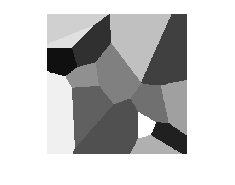

Plano=zeros(256);
Sds=[];
for c=1:16
    sx=randi(256);
    sy=randi(256);
    color=c*16;
    Plano(sx,sy)=c;
    s=[sx,sy,color];
    Sds=[Sds;s];
end
dmin=256;
[imax,jmax]=size(Plano);
for i=1:imax
    for j= 1:jmax
        for k=Sds'
            x1=i;
            y1=j;
            x2=k(1);
            y2=k(2);
            d=sqrt(((x1-x2)^2)+((y2-y1)^2));
            if d<dmin
                dmin=d;
                Plano(i,j)=k(3);
            end
        end
        dmin=256;
    end
end
Sds;
imshow(uint8(Plano))

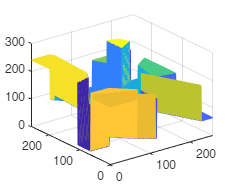

mesh(Plano)